# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 26-Nov-2024 19:28:06

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 14);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Time", "LE", "F4", "C4", "P4", "P3", "C3", "F3", "Trigger", "Time_Offset", "ADC_Status", "ADC_Sequence", "Event", "Comments"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "char"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Comments", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Comments", "EmptyFieldRule", "auto");

% Import the data
WFR1 = readtable("/Users/gayatrimalladi/Desktop/untitled folder/Prof_Mat_pre_stroke/WFR1.txt", opts)

WFR1 = 19005×14 table
     Time      LE        F4       C4        P4       P3       C3       F3      Trigger    Time_Offset    ADC_Status    ADC_Sequence    Event      Comments  
    ______    _____    ______    _____    ______    _____    ____    ______    _______    ___________    __________    ____________    _____    ____________

       NaN      NaN       NaN      NaN       NaN      NaN     NaN       NaN      NaN          NaN           NaN            NaN          NaN     {'Comments'}
    0.0033    -86.7     127.9 

## Clear temporary variables

clear opts
% Extract EEG channels
eeg_channels = WFR1{:, ["LE", "F4", "C4", "P4", "P3", "C3", "F3"]};

% Check for NaN or Inf in the EEG channels
if any(~isfinite(eeg_channels(:)))
    eeg_channels(~isfinite(eeg_channels)) = 0; % Replace non-finite values with zeros
end

% Define sampling frequency and channel names
sfreq = 300; % Sampling frequency in Hz
ch_names = {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}; % Channel names

% Apply notch filter to remove powerline noise
notch_freqs = [50, 60]; % Frequencies to remove
for i = 1:length(notch_freqs)
    d = designfilt('bandstopiir', 'FilterOrder', 2, ...
        'HalfPowerFrequency1', notch_freqs(i) - 1, ...
        'HalfPowerFrequency2', notch_freqs(i) + 1, ...
        'SampleRate', sfreq);
    eeg_channels = filtfilt(d, eeg_channels); % Apply filter
end

% Define bandpass filter parameters
low_freq = 7;  % Lower cutoff frequency (Hz)
high_freq = 14; % Upper cutoff frequency (Hz)

% Design a bandpass filter
[b, a] = butter(4, [low_freq high_freq] / (sfreq / 2), 'bandpass');

% Apply the bandpass filter to the EEG data
filtered_data = filtfilt(b, a, eeg_channels);

% Display a summary of the filtered data
disp('Filtered EEG data:');

Filtered EEG data:


disp(filtered_data);

    1.0726   -1.4081    0.5153    0.2010    1.2004   -0.0707   -1.2187
   46.1584  -63.3337   14.7517   55.0360   81.2741    6.7450  -61.6687
   88.8852 -121.9988   28.2053  106.9731  157.1310   13.2036 -118.9152
  127.1457 -174.4907   40.2132  153.4488  225.0010   18.9775 -170.1105
  159.0958 -218.2627   50.1988  192.2255  281.5872   23.7797 -212.7663
  183.2591 -251.2792   57.7043  221.5189  324.2554   27.3808 -244.8965
  198.6077 -272.1272   62.4160  240.0951  351.1786   29.6220 -265.1260
  204.6122 -280.0866   64.1790  247.3306  361.4278   30.4233 -272.7596
  201.2600 -275.1552   63.0024  243.2334  355.0045   29.7865 -267.8049
  189.0411 -258.0269   59.0536  228.4223  332.8129   27.7928 -250.9519
  168.9017 -230.0285   52.6431  204.0697  296.5776   24.5958 -223.5090
  142.1725 -193.0174   44.2002  171.8106  248.7110   20.4097 -187.3031
  110.4748 -149.2513   34.2431  133.6273  192.1434   15.4941 -144.5507
   75.6132 -101.2374   23.3441   91.7159  130.1280   10.1369  -97.7099
   39.


% Compute statistics
stats.mean = mean(eeg_channels, 1); % Mean
stats.variance = var(eeg_channels, 0, 1); % Variance
stats.std_dev = std(eeg_channels, 0, 1); % Standard Deviation
stats.median = median(eeg_channels, 1); % Median
stats.min = min(eeg_channels, [], 1); % Minimum
stats.max = max(eeg_channels, [], 1); % Maximum

% Display statistics
disp('Statistics for EEG Channels:');

Statistics for EEG Channels:


disp(array2table([stats.mean; stats.variance; stats.std_dev; stats.median; stats.min; stats.max], ...
    'VariableNames', ["LE", "F4", "C4", "P4", "P3", "C3", "F3"], ...
    'RowNames', {'Mean', 'Variance', 'StdDev', 'Median', 'Min', 'Max'}));

                  LE         F4          C4          P4          P3         C3          F3   
                _______    _______    ________    ________    ________    _______    ________

    Mean         2.5317    -3.0034    -0.61717    0.011667     0.65302    0.48499     -2.7995
    Variance     655.36     1402.1      651.76        1075      3138.4     193.24      1075.8
    StdDev         25.6     37.445       25.53      32.787      56.022     13.901      32.799
    Median      -1.1568     4.3231     -4.7523     -1.2126    -0.29644    -1.5342    -0.70076
    Min         -55.431     -719.8     -101.07     -103.51     -820.66    -135.04     -698.24
    Max   

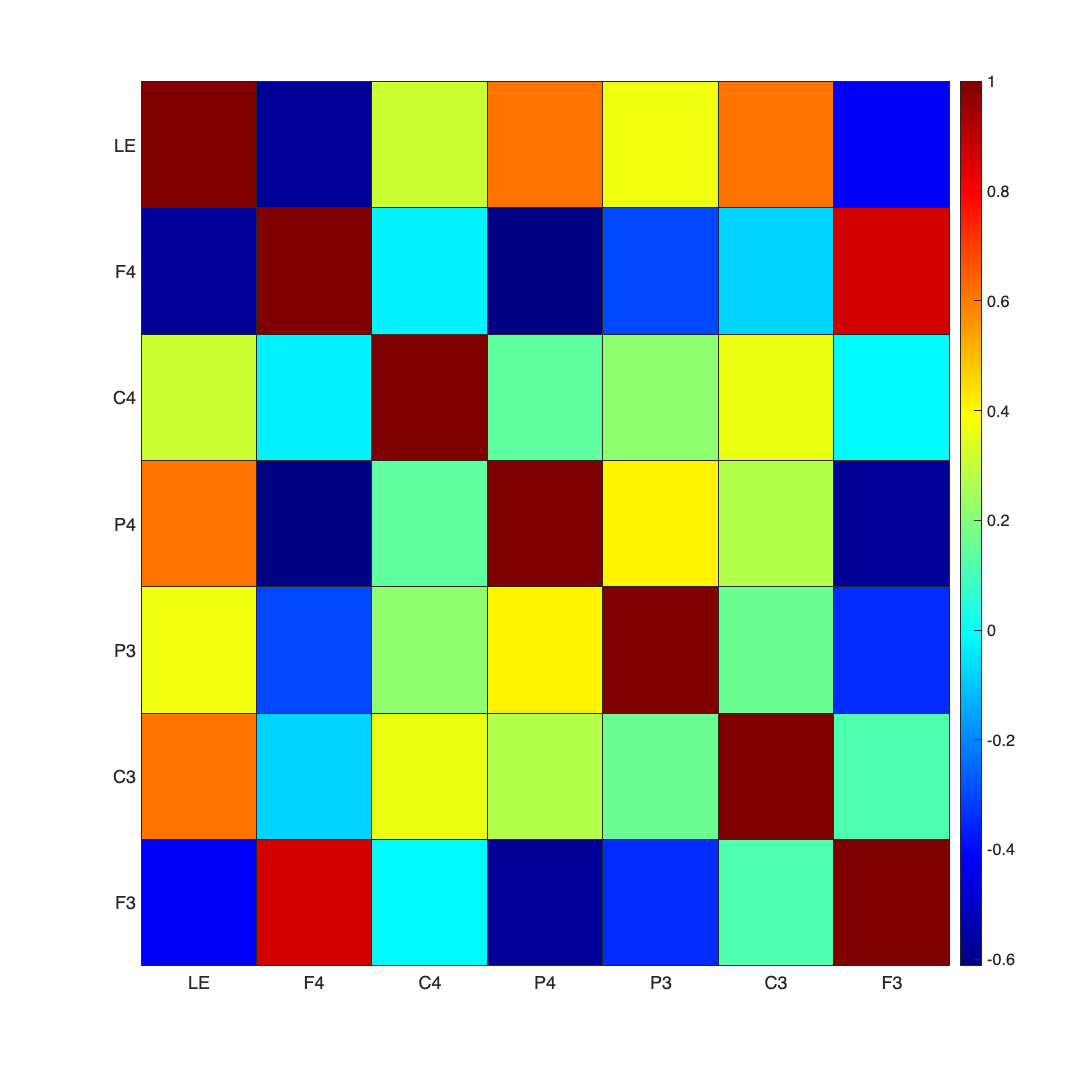


% Compute the correlation matrix
correlation_matrix = corr(eeg_channels);

% Plot correlation matrix as heatmap
figure('Name', 'EEG Correlation Matrix', 'Position', [100, 100, 800, 800]);
heatmap(["LE", "F4", "C4", "P4", "P3", "C3", "F3"], ...
        ["LE", "F4", "C4", "P4", "P3", "C3", "F3"], ...
        correlation_matrix, ...
        'Colormap', jet, ...
        'ColorbarVisible', 'on', ...
        'CellLabelColor', 'none'); % Optional to hide correlation labels
title('Correlation Matrix for EEG Channels');

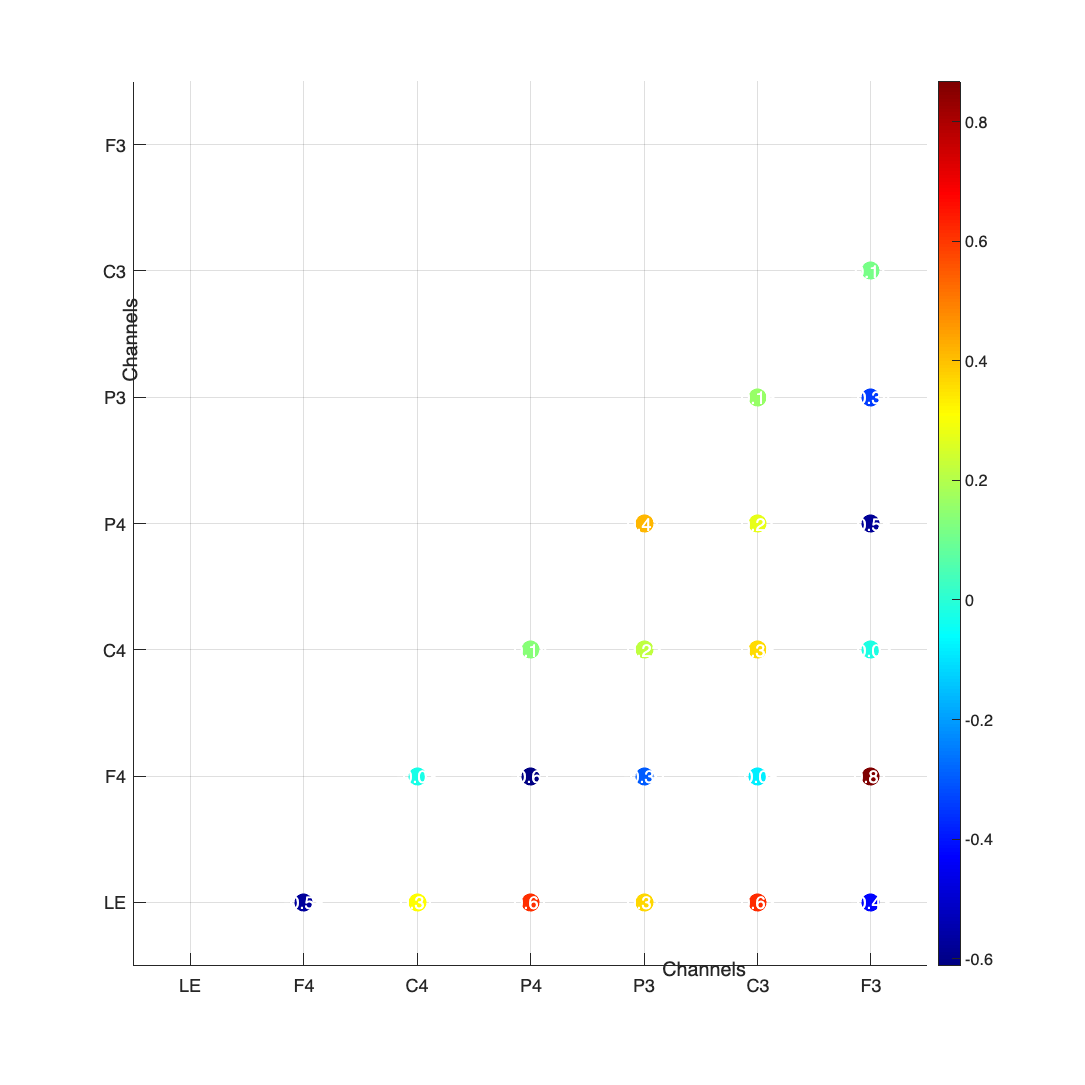


% Generate correlation plot
figure('Name', 'Triangular Correlation Plot', 'Position', [100, 100, 800, 800]);
hold on;
n_channels = size(correlation_matrix, 1);
for i = 1:n_channels
    for j = 1:i
        if i ~= j
            scatter(i, j, 100, correlation_matrix(i, j), 'filled');
            text(i, j, sprintf('%.2f', correlation_matrix(i, j)), ...
                'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'w');
        end
    end
end
colormap(jet);
colorbar;
xlim([0.5, n_channels + 0.5]);
ylim([0.5, n_channels + 0.5]);
xticks(1:n_channels);
yticks(1:n_channels);
xticklabels(["LE", "F4", "C4", "P4", "P3", "C3", "F3"]);
yticklabels(["LE", "F4", "C4", "P4", "P3", "C3", "F3"]);
xlabel('Channels');
ylabel('Channels');
title('Triangular Correlation Plot');
grid on;
hold off;

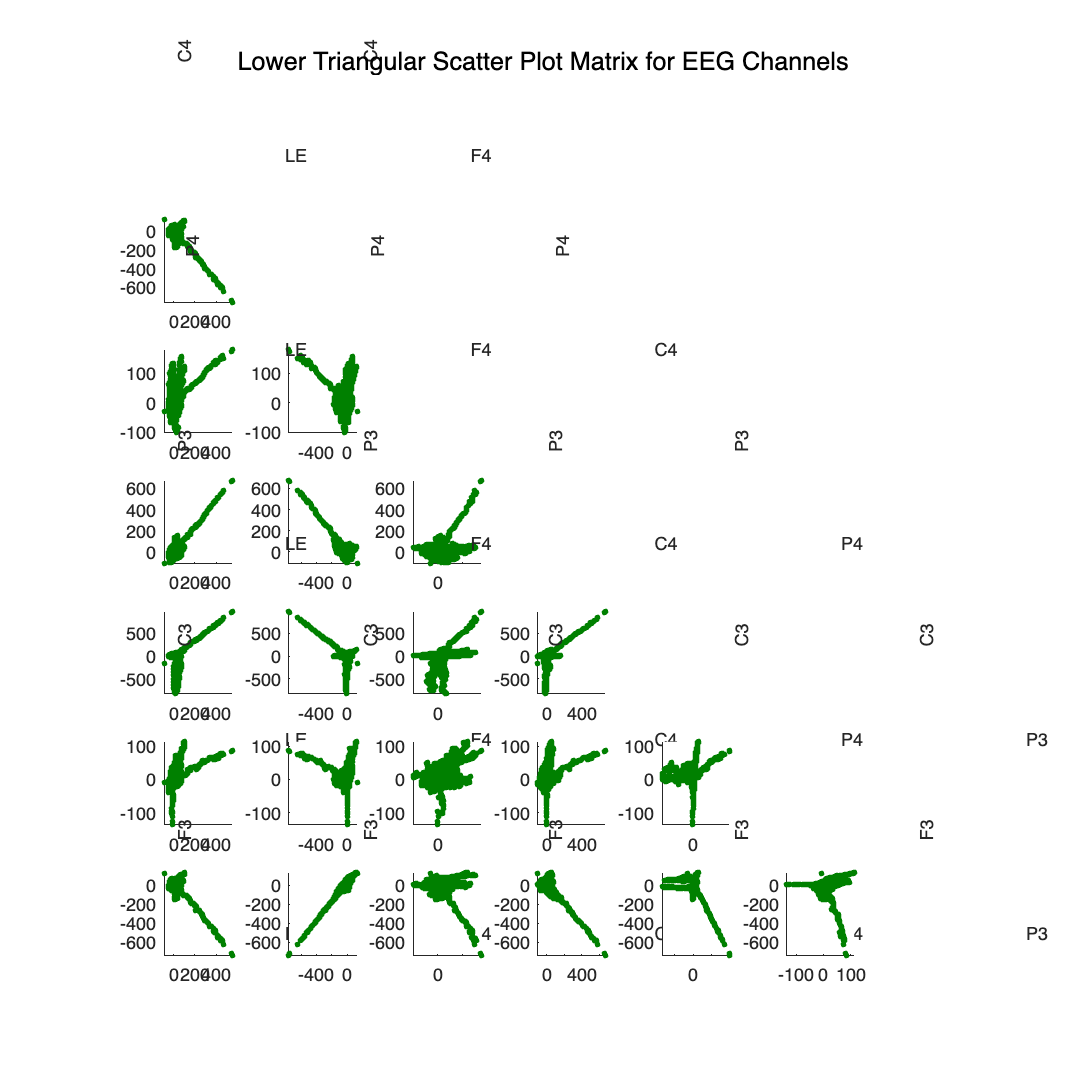

% Extract relevant variables from WaveFistRub1
eeg_channels = WFR1{:, ["LE", "F4", "C4", "P4", "P3", "C3", "F3"]};
channel_names = ["LE", "F4", "C4", "P4", "P3", "C3", "F3"];
num_channels = size(eeg_channels, 2);

% Create figure for scatter plot matrix
figure('Name', 'Scatter Plot Matrix for EEG-1 Channels', 'Position', [100, 100, 1000, 1000]);

for i = 2:num_channels
    for j = 1:i-1
        % Plot the scatter plot with dark green dots
        subplot(num_channels, num_channels, (i-1) * num_channels + j);
        scatter(eeg_channels(:, j), eeg_channels(:, i), 10, [0, 0.5, 0], 'filled'); % Dark green color for dots
        xlabel(channel_names(j), 'FontSize', 10);
        ylabel(channel_names(i), 'FontSize', 10);
        xlim([min(eeg_channels(:, j)) max(eeg_channels(:, j))]);
        ylim([min(eeg_channels(:, i)) max(eeg_channels(:, i))]);
    end
end

% Remove upper triangle subplots to create lower triangular matrix
for i = 1:num_channels
    for j = i:num_channels
        subplot(num_channels, num_channels, (i-1) * num_channels + j);
        axis off;
    end
end

% Title for the scatter plot matrix
sgtitle('Lower Triangular Scatter Plot Matrix for EEG Channels', 'FontSize', 14);


% Read additional data from another file
data = readtable("/Users/gayatrimalladi/Desktop/untitled folder/Prof_Mat_pre_stroke/WFR1.txt"); 

% Extract EEG channels and time from the new data
eeg_channels = data{:, {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}};
time = data{:, 'Time'};

% Extract EEG channels
eeg_channels = WFR1{:, ["LE", "F4", "C4", "P4", "P3", "C3", "F3"]};
% 1. Zero Crossing Rate
zero_crossing_rate = sum(diff(sign(eeg_channels)) ~= 0, 1) / size(eeg_channels, 1);
disp(zero_crossing_rate)

    0.0685    0.0574    0.0445    0.0550    0.0622    0.0889    0.0704




% 2. Skewness
skewness_val = skewness(eeg_channels, 0, 1);
disp(skewness_val)

    6.8978   -6.1966    1.4420    5.8970   -3.1256    1.6646   -6.5536




% 3. Kurtosis
kurtosis_val = kurtosis(eeg_channels, 0, 1);
disp(kurtosis_val)

   99.3968   74.9376    7.6745   84.8945  115.2142   13.8043  102.4693



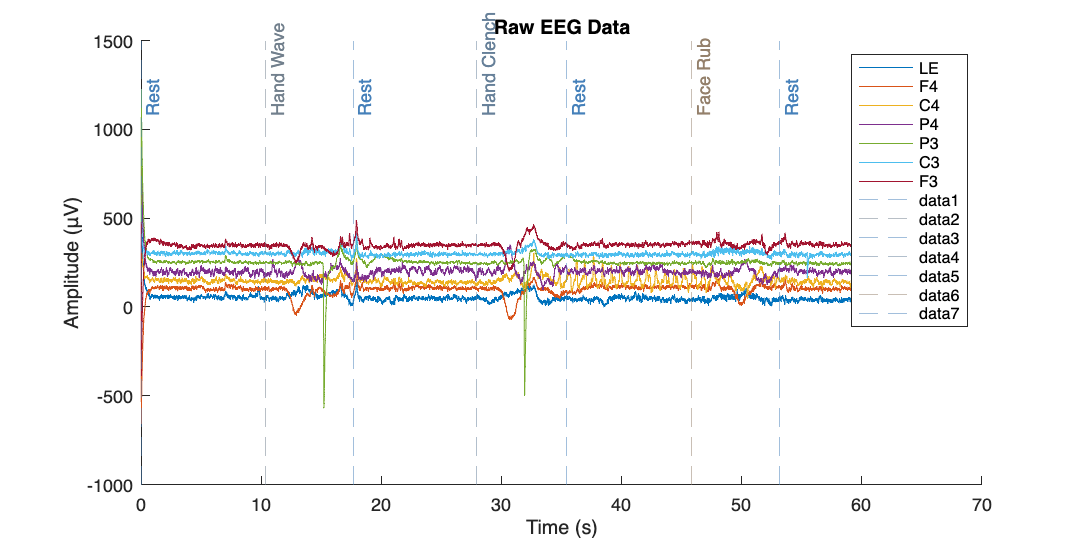

% Extract relevant data
time = data.Time; 
comments = data.Comments; 
eeg_channels = data{:, {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}}; % EEG channels
ch_names = {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}; % Channel names
sfreq = 300; % Sampling frequency
% Step 1: Parse comments and timestamps
comment_timestamps = [];
comment_names = {};
for i = 1:height(data)
    if ischar(data.Comments{i}) && ~isempty(strtrim(data.Comments{i}))
        comment_timestamps(end+1) = data.Time(i); % Add timestamp
        comment_names{end+1} = data.Comments{i}; % Add comment
    end
end
% Step 2: Generate a color for each comment
hash = @(str) mod(sum(double(str) .* (1:length(str))), 256); % Simple hash function
name_to_color = @(name) [hash(name)/255, 0.5, 1 - hash(name)/255]; % Generate RGB colors
% Step 3: Plot raw EEG data
figure('Name', 'Raw EEG Data', 'Position', [100, 100, 1000, 500]);
colors = lines(length(ch_names)); % Define colors for channels

hold on;
for i = 1:size(eeg_channels, 2)
    plot(time, eeg_channels(:, i) + i * 50, 'Color', colors(i, :), 'DisplayName', ch_names{i}); % Offset each channel for clarity
end
% Add vertical lines and labels for comments
for i = 1:length(comment_timestamps)
    comment_color = name_to_color(comment_names{i});
    xline(comment_timestamps(i), '--', 'Color', comment_color, 'Alpha', 0.5);
    text(comment_timestamps(i), max(max(eeg_channels)) + 100, comment_names{i}, ...
        'Rotation', 90, 'VerticalAlignment', 'top', 'Color', comment_color);
end

title('Raw EEG Data');
xlabel('Time (s)');
ylabel('Amplitude (μV)');
legend('show');
hold off;

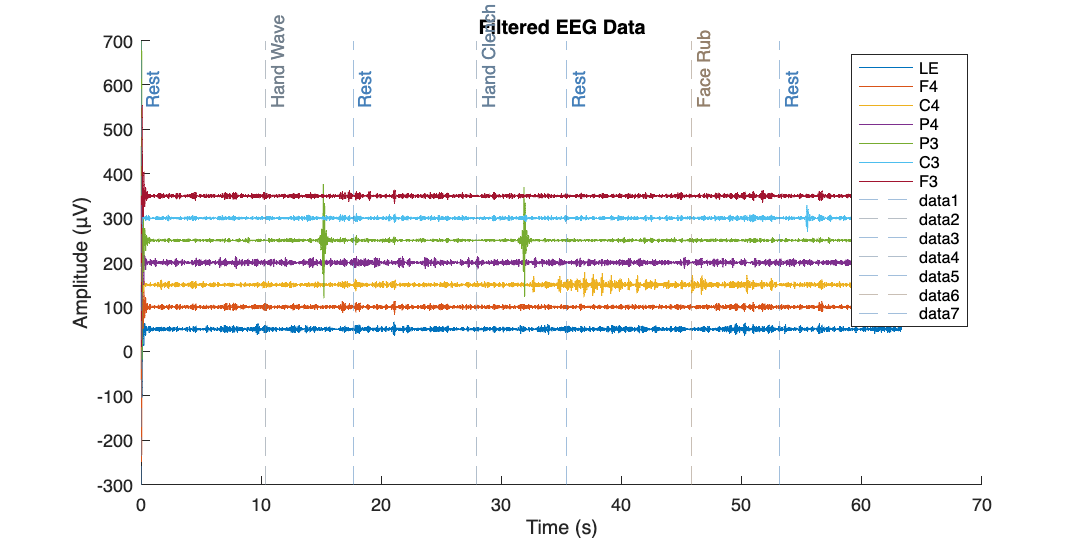

% Step 4: Apply filters (notch and bandpass)
notch_freqs = [50, 60];
for f = notch_freqs
    d = designfilt('bandstopiir', 'FilterOrder', 2, ...
        'HalfPowerFrequency1', f - 1, ...
        'HalfPowerFrequency2', f + 1, ...
        'SampleRate', sfreq);
    eeg_channels = filtfilt(d, eeg_channels); % Apply notch filter
end
% Bandpass filter
low_freq = 7; high_freq = 14;
[b, a] = butter(4, [low_freq high_freq] / (sfreq / 2), 'bandpass');
filtered_data = filtfilt(b, a, eeg_channels);
% Step 5: Plot filtered EEG data
figure('Name', 'Filtered EEG Data', 'Position', [100, 100, 1000, 500]);
hold on;
for i = 1:size(filtered_data, 2)
    plot(time, filtered_data(:, i) + i * 50, 'Color', colors(i, :), 'DisplayName', ch_names{i}); % Offset each channel
end
% Add vertical lines and labels for comments
for i = 1:length(comment_timestamps)
    comment_color = name_to_color(comment_names{i});
    xline(comment_timestamps(i), '--', 'Color', comment_color, 'Alpha', 0.5);
    text(comment_timestamps(i), max(max(filtered_data)) + 100, comment_names{i}, ...
        'Rotation', 90, 'VerticalAlignment', 'top', 'Color', comment_color);
end
title('Filtered EEG Data');
xlabel('Time (s)');
ylabel('Amplitude (μV)');
legend('show');
hold off;

% Step 6: Time-frequency analysis using wavelet transform
frequencies = 1:80; % Frequencies of interest
n_cycles = frequencies / 2; % Number of cycles in the wavelet
time_range = 1:length(time) / sfreq;
% Morlet wavelet analysis
[power_raw, ~] = cwt(eeg_channels(:, 1), sfreq, 'FrequencyLimits', [min(frequencies) max(frequencies)]); % Example on channel 1
[power_filtered, ~] = cwt(filtered_data(:, 1), sfreq, 'FrequencyLimits', [min(frequencies) max(frequencies)]); % Example on channel 1
% Plot time-frequency analysis for raw data
figure('Name', 'Time-Frequency Analysis (Raw)', 'Position', [100, 100, 1000, 500]);
